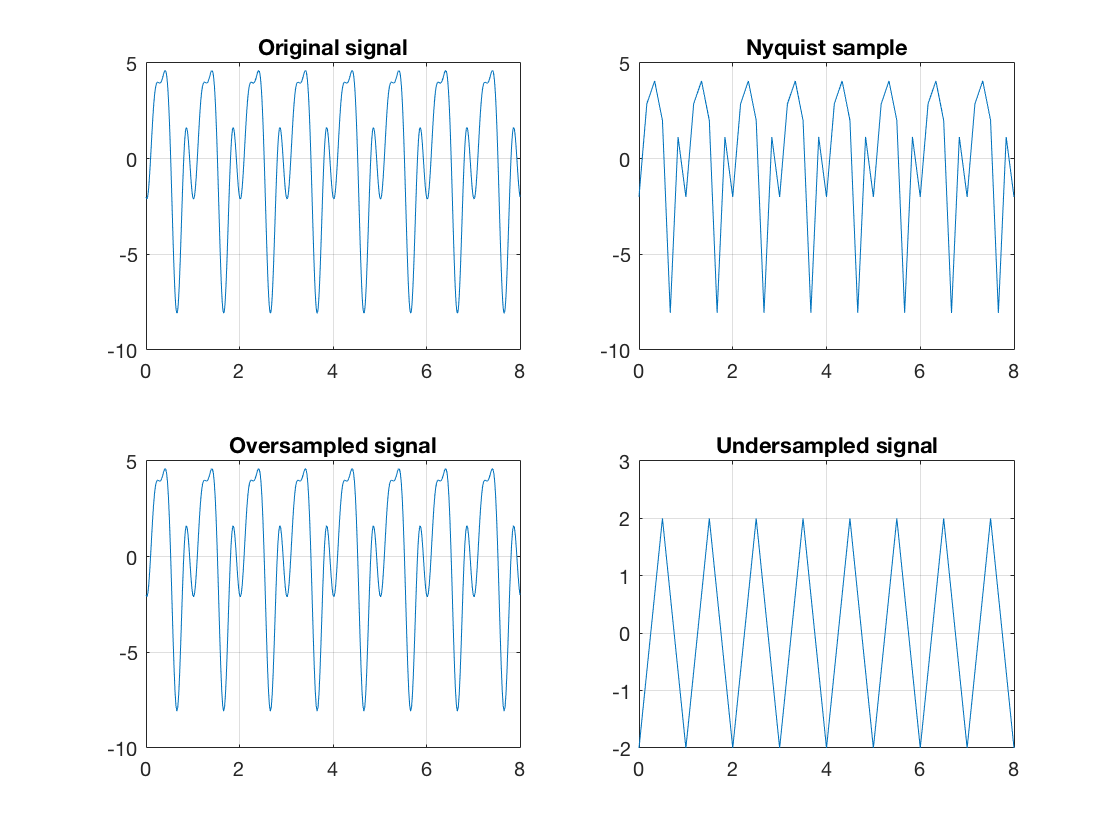

close all, clear all 
%Nyquist - Shannon sampling frequency: 6Hz >= 3Hz
dt1 = 1/100; %Original sampling rate
dt2 = 1/6; %Nyquist sampling rate
dt3 = 1/50; %Higher sampling than Nyquist
dt4 = 1/2; %Less sampling than Nyquist

st = 0;
et = 8;
t1 = st:dt1:et;
t2 = st:dt2:et;
t3 = st:dt3:et;
t4 = st:dt4:et;

%Original signal
y1 = 4*sin(2*pi*t1)-2*cos(6*pi*t1)-3*sin(4*pi*t1);
%Nyquist sample signal
y2 = 4*sin(2*pi*t2)-2*cos(6*pi*t2)-3*sin(4*pi*t2);
%Oversampled signal
y3 = 4*sin(2*pi*t3)-2*cos(6*pi*t3)-3*sin(4*pi*t3);
%Undersampled signal
y4 = 4*sin(2*pi*t4)-2*cos(6*pi*t4)-3*sin(4*pi*t4);

subplot(2,2,1)
plot(t1,y1), grid on, title('Original signal')
subplot(2,2,2)
plot(t2,y2), grid on, title('Nyquist sample')
subplot(2,2,3)
plot(t3,y3), grid on, title('Oversampled signal')
subplot(2,2,4)
plot(t4,y4), grid on, title('Undersampled signal')